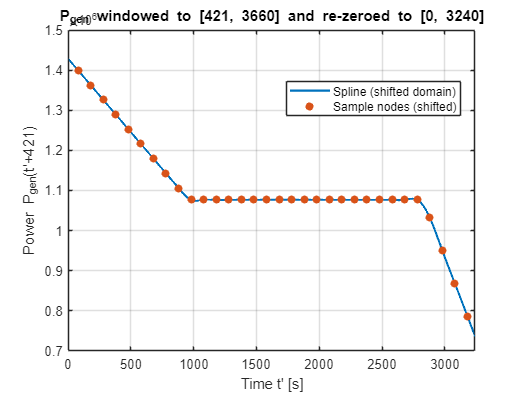

%% Plot P_gen windowed to original [421, 3660] and re-zeroed to [0, 3240]
% Run the whole script so MATLAB sees the local function defined below.

t0 = linspace(0, 3240, 2001);         % new domain
p0 = P_gen_0to3240(t0);

figure
plot(t0, p0, 'LineWidth', 1.6); grid on
xlabel('Time t'' [s]'); ylabel('Power P_{gen}(t''+421)');
title('P_{gen} windowed to [421, 3660] and re-zeroed to [0, 3240]')
xlim([0 3240])

% Overlay shifted original 100-s sample nodes
tn_all   = 1:100:4500;                 % original knot times (1..4401)
mask     = (tn_all >= 421) & (tn_all <= 3660);
tn_shift = tn_all(mask) - 421;         % now 0..3240
pn_shift = P_gen_0to3240(tn_shift);

hold on
scatter(tn_shift, pn_shift, 35, 'filled')
xline(0,'--'); xline(3240,'--');
legend('Spline (shifted domain)','Sample nodes (shifted)','Location','best')



%% Local function (keeps your data/code, just shifts t by +421 and crops to 0..3240)

function power = P_gen_0to3240(tprime)
% New domain: t' in [0, 3240] corresponds to original t = t' + 421

    % --- Your original power samples ---
    power_values = [1560823.08194895, 1546158.09929008, 1509495.64264034, ...
                    1472833.18607241, 1436170.72952995, 1399508.27275915, ...
                    1362845.81599425, 1326183.35924518, 1289520.90255232, ...
                    1252858.44584885, 1216195.98916551, 1179533.53247727, ...
                    1142871.07579598, 1106208.61911061, 1076878.65376792, ...
                    1076878.65376794, 1076878.65376796, 1076878.65376799, ...
                    1076878.65376802, 1076878.65376803, 1076878.65376804, ...
                    1076878.65376805, 1076878.65376806, 1076878.65376806, ...
                    1076878.65376806, 1076878.65376806, 1076878.65376805, ...
                    1076878.65376804, 1076878.65376803, 1076878.65376802, ...
                    1076878.65376799, 1076878.65376797, 1076878.65376798, ...
                    1032182.62799974, 950257.879125699, 868333.130251657, ...
                    786408.381377613, 704483.632503570, 622558.883629528, ...
                    540634.134755485, 458709.385881442, 376784.637007400, ...
                    294859.888133355, 212935.139259313, 58628.9592331873];

    % --- Your original time vector (1,101,...,4401) ---
    time_vector = 1:100:4500;

    % Validate input in the new domain [0, 3240]
    if any(tprime(:) < 0 | tprime(:) > 3240)
        error('t'' must be within 0 to 3240 seconds.');
    end

    % Build spline on the original samples, then evaluate at shifted time t = t' + 421
    spline_fit = spline(time_vector, power_values);
    power = ppval(spline_fit, tprime + 421);
end